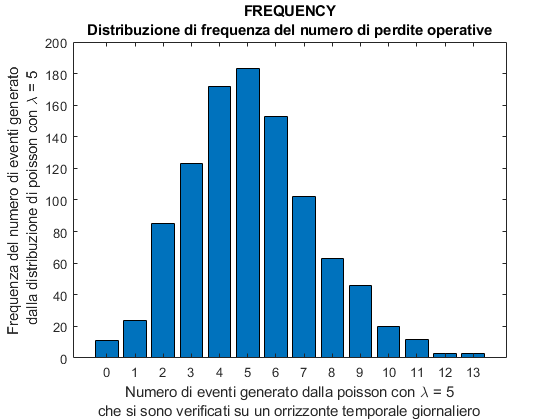

% PROGETTO Descrivere l’approccio attuariale alla misurazione del rischio 
% operativo
clc
clear

% PARAMETRI A DISCREZIONE DELL'UTENTE. Questi, nel nostro caso, sono stati
% definiti nella consegna dell'approfondimento che ci è stato assegnato.
mu=[1.5 1.5 3];
lambda=5;
var=[1 2 1];
% Calcoliamo la deviazione standard che verrà utilizzata nella funzione 
% lognrnd che genererà valori casuali da una distribuzione Log-normale 
% con parametri mu e sigma. La radice della varianza ci restituisce
% il valore desiderato.
sigma=sqrt(var);
% Definiamo il numero di ripetizioni della simulazione. All'aumentare di n
%  di n, migliore sarà la precisione della simulazione e la rappresentazione
% della distribuzione delle perdite potendo far affidamento a un numero
% maggiore di scenari simulati.
% Al contrario, all'aumentare di n, maggiore sarà il lavoro computazionale
% di calcolo.
n=1000;
% Definiamo alpha come il livello di confidenza, come definito nella consegna
% relativo al calcolo del VAR. Questo, sta a significare che al 99% dei casi 
% la perdita non supererà il valore L_Var trovato. Nel restante 1% dei casi 
% però, non ci sono informazioni a riguardo della possibile perdita.
alpha=0.99;

k = poissrnd(lambda,n,1);
%distribuzione di poisson utile perchè:
%1)si possono aggregare più distribuzioni di poisson legati al rischio 
%operativo dei tipo di eventi delle business line (ipotesi di indipendenza
%degli eventi nel tempo) PROPRIETA' ADDITIVA
%2)semplice da implementare, basta conoscere il numero medio di volte che
%l'evento si verifica in un arco di tempo (lambda)

%le variabili x hanno distribuzione log normale
s=1;
% calcoliamo i valori di massimo e minimo di k per conoscere l'intervallo 
% dei valori di k (a step di 1) che verranno contati, e dei quali verrà 
% rappresentata la frequenza nel grafico a barre
max=max(k);
min=min(k);
% settiamo la matrice x come una matrice di zeri di dimensioni massime pari 
% a max x max, cioè pari al valore massimo di perdite operative che si possono
% avere sull'orizzonte temporale giornaliero.
x=zeros(max,max);
% l'obiettivo del ciclo è quello di calcolare le perdite operative sulla base 
% di valori casuali generati da una distribuzione Log-normale con parametri 
% definiti nei 3 diversi casi. I valori di ogni colonna della matrice x, 
% verranno sommati calcolando così la perdita L legata all'i-esimo event type 
% e alla j-esima business line. Il ciclo viene ripetuto n volte permettendo
% così la rappresentazione della distribuzione di perdita.
for p=1:3
    for i=1:n
        x(1:k(i),s)=lognrnd(mu(p),sigma(p),k(i),1);
        s=s+1;     
        if s==n+1
            s=1;
            break
        end
    end
    % Calcolo della perdita totale della j-esima business line come somma 
    % delle k perdite Xi.
    L(p,:)=sum(x); 
    % Ordiniamo le perdite per poter successivamente costruire l'istogramma
    % con le frequenze degli intervalli di perdita.
    L_sort(p,:)=sort(L(p,:));
    % Calcolo del VAR con un livello di confidenza del 99% (alpha)
    L_var(p)=quantile(L_sort(p,:),alpha);
end
% calcoliamo il valore atteso delle perdite per ogni simulazione. Il valore
% trovato verrà utilizzato per il calcolo del Capital at Risk
L_mean=mean(L');
% calcolo del Capital at Risk come differenza tra il Var calcolato come 99°
% quantile della distribuzione di L e il valore atteso delle perdita.
C_ar=L_var-L_mean;
%definizione de
edges = min:1:max;
% tramite la funzione histc, contiamo i valori contenuti in edges che si
% osservano nel vettore k generato casualmente dalla distribuzione di Poisson.
% Dopodichè, si costruisce il grafico a barre contenente la frequenza dei valori 
% casualmente generati.
m= histc(k,edges);
bar(edges,m);
% integrazione del grafico con legenda e descrizione degli assi
title({'FREQUENCY','Distribuzione di frequenza del numero di perdite operative giornaliere'});
ylabel({'Frequenza del numero di eventi generato',[' dalla distribuzione di poisson con \lambda = ' num2str(lambda)]});
xlabel({['Numero di eventi generato dalla poisson con \lambda = ' num2str(lambda)],'che si sono verificati su un orrizzonte temporale giornaliero'});

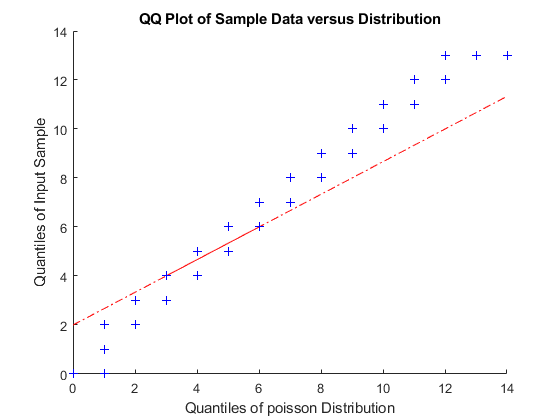

% costruzione del qqplot utile per analizzare se la distribuzione teorica 
% utilizzata, in questo caso una Log-normale approssima correttamente i 
% valori casualmente generati. Nel nostro caso, avendo definito a priori 
% la distribuzione di k come una Poisson, l'approssimazione risulterà
% discostarci in maniera significativa dalla stessa distribuzione teorica 
% di Poisson
qqplot(k,makedist('Poisson','lambda',5))

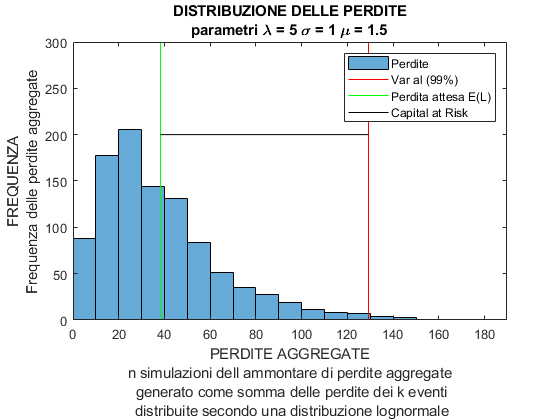

% Costruzione dell'istogramma che rappresenta la distribuzione di perdita
% nei 3 diversi casi con diversi parametri mu e sigma.
% Nel grafico è rappresentato il VAR al 99%, come 99° quantile della 
% distribuzine continua delle perdite e il valore atteso delle perdite come
% media delle n simulazioni. La differenza rappresenta il Capital at Risk,
% cioè il capitale che l abanca rischia di perdere dovuto a perdite inattese.
% PRIMO CASO: lambda = 5 mu = 1.5 sigma = 1
histogram(L_sort(1,:));
title({'DISTRIBUZIONE DELLE PERDITE',['parametri \lambda = ' num2str(lambda) ' \sigma = ' num2str(sigma(1)) ' \mu = ' num2str(mu(1))]});
hold on
plot([L_var(1),L_var(1)],[0 300],'r');
plot([L_mean(1),L_mean(1)],[0 300],'g');
plot([L_mean(1),L_var(1)],[200 200],'k');
legend('Perdite','Var al (99%)','Perdita attesa E(L)','Capital at Risk');
axis([0 L_sort(1,end) 0 300])
ylabel({'FREQUENZA','Frequenza delle perdite aggregate'});
xlabel({'PERDITE AGGREGATE','n simulazioni dell ammontare di perdite aggregate',' generato come somma delle perdite dei k eventi',' distribuite secondo una distribuzione lognormale'});
hold off

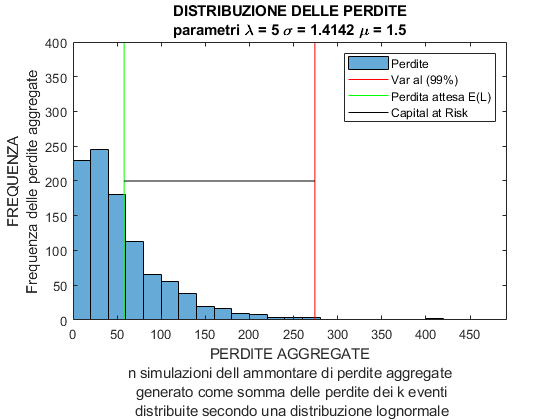

% SECONDO CASO: lambda = 5 mu = 1.5 sigma = 1.4142
histogram(L_sort(2,:));
title({'DISTRIBUZIONE DELLE PERDITE',['parametri \lambda = ' num2str(lambda) ' \sigma = ' num2str(sigma(2)) ' \mu = ' num2str(mu(2))]});
hold on
plot([L_var(2),L_var(2)],[0 400],'r');
plot([L_mean(2),L_mean(2)],[0 400],'g');
plot([L_mean(2),L_var(2)],[200 200],'k');
legend('Perdite','Var al (99%)','Perdita attesa E(L)','Capital at Risk');
axis([0 L_sort(2,end) 0 400])
ylabel({'FREQUENZA','Frequenza delle perdite aggregate'});
xlabel({'PERDITE AGGREGATE','n simulazioni dell ammontare di perdite aggregate',' generato come somma delle perdite dei k eventi',' distribuite secondo una distribuzione lognormale'});
hold off

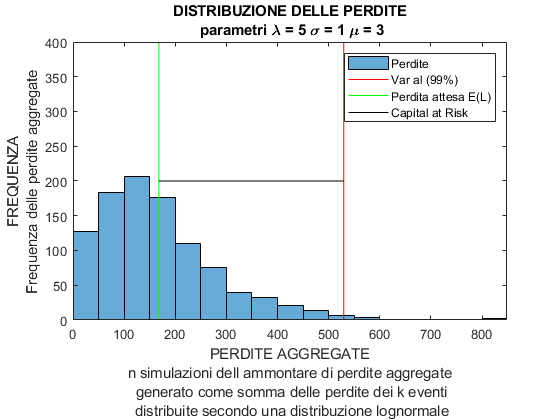

% TERZO CASO: lambda = 5 mu = 3 sigma = 1
histogram(L_sort(3,:));
title({'DISTRIBUZIONE DELLE PERDITE',[' parametri \lambda = ' num2str(lambda) ' \sigma = ' num2str(sigma(3)) ' \mu = ' num2str(mu(3))]});
hold on
plot([L_var(3),L_var(3)],[0 400],'r');
plot([L_mean(3),L_mean(3)],[0 400],'g');
plot([L_mean(3),L_var(3)],[200 200],'k');
legend('Perdite','Var al (99%)','Perdita attesa E(L)','Capital at Risk');
axis([0 L_sort(3,end) 0 400])
ylabel({'FREQUENZA','Frequenza delle perdite aggregate'});
xlabel({'PERDITE AGGREGATE','n simulazioni dell ammontare di perdite aggregate',' generato come somma delle perdite dei k eventi',' distribuite secondo una distribuzione lognormale'});
hold off